# Final Project Notebook

# Diffusion of Air Bubbles in Ice

## By: Lorenzo Caseiro and Matthew Adams

## EAS 4610

## Fall 2023

## **Introduction**

    Glacial ice on the Earth can provide evidence of the state of the planet's past climatic conditions. Air can be trapped within the ice and act as a time capsule that records the atmospheric composition of times past. The air is trapped when continual snowfall buries it under deeper layers of snow until the layer eventually solidifies to ice under increased pressure. This is known as the "bubble closeoff depth" and it is the point at which the bubbles are fully formed and solidified within the ice (Bender et al 1997). The air bubbles provide evidence of certain trace gases, such as methane or carbon dioxide, and their concentration at the time the ice formed (Legend and Mayewski 1997).

    Many modern day researchers use these gas bubbles to measure past climate conditions, and it is invaluable in determining the anthropogenic changes to the Earth's climate. Much of the contmeporary study of this topic focuses on extracting ice cores from the glacial ice sheets that hold the trapped bubbles of air. The ice cores, and the gas bubbles within them, can be studied for paleoclimatologic and paleoceanographic purposes. However, this model, created using information from "Mathematical Modeling of earth's Dynamical Systems: A Primer", does not focus specifically on the results that ice cores can yield. Instead, it models an important consideration that is essential for obtiaing accurate results from the study of ice cores: diffusion of gas bubbles within glacial ice. Gas trapped in glacial ice can diffuse according to Fick's law, and this model seeks to follow how gas would diffuse within a given ice sheet (Singerland and Kump 2006). This information allows for proper tracking of gas within the ice and will yield more accurate results when reconstructing paleoclimate concentrations.

## **Equations**

    The most important process this model uses is the advection-diffusion equation. This equation can be used to describe phenomena that undergo both advection and diffusion within the system. Diffusion is defined as the movement of molecules across a concentration gradient, and it is an essential process when studying air bubbles trapped in ice (Slingerland and Kupp 2006). Using this law, the model can simulate changes in concentration of a desired gaseous species in terms of both time and space (or depth in this case). The Oxford English Dictionary defines advection as "the transfer of heat or matter by the flow of a fluid." Advection is another important process to consider for this model as new layers of snowfall continue to pile on ice sheets and cause advective transport within the system. The advection-diffusion utilizes partial derivatives to model both of the previously described physical processes in a system.

## 
$$\frac{\partial J}{\partial t}+u*\frac{\partial J}{\partial x}=D*\frac{\partial^2 J}{\partial x^2 }$$


D = diffusivity

t = time

x = position

J = concentration

u = fluid velocity

**Equation 1: **Advection-diffusion equation

    The above equation utilizes several important parameters that should be defined to further understand the model. Diffusivity, also known as a diffusion coefficient, is a constant that is unique for a given substance that is undergoing diffusion. The diffusion coeffecient in this model utilizes units of square meters per year. The variable used for time, tracked in years, is essential for tracking the changes in concentration of a substance as a function of time. In this model, the position variable refers to the depth of a gas bubble within an ice sheet measured in meters. The fluid velocity variable is derived from the advection portion of the equation and it is defined as the snowfall rate in meters per year in this scenario. Finally, the concentration is the output of the model and describes the concentration of a diffused substance in moles. Additionally, the model uses a diffusion number that is integral for solving the diffusion equation. Similarly to the diffusion number, the advection part of the reaction has a dimensionless parameter, known as the courant number, that must be used to solve the equation. These terms are defined below.

## 
$$C_D =\frac{D*\Delta t}{\Delta x^2 }$$


**Equation 2: **Equation defining the diffusion number term.

## 
$$C=\frac{u*\Delta t}{\Delta x}$$


**Equation 3: **Equation defining the courant number term.

    The discretization of the advection-diffusion equation below is used by this model to solve for unknown concentration values. It isolates an unknown concentration value on one side of the equation, and it can then be used as a marching equation to obtain approximations for concentration.

## (a) $\frac{\partial J}{\textrm{dt}}+u*\frac{\partial J}{\partial x}-D*\frac{\partial^2 J}{\partial x^2 }=0$

## (b) $\frac{\partial J}{\partial t}=\frac{J_i^{k+1} -J_i^k }{\Delta t}$, $\frac{\partial J}{\partial x}=\frac{J_i^k -J_{i-1}^k }{\Delta x}$, $\frac{\partial^2 J}{\partial x^2 }=\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }$

## (c) $\frac{J_i^{k+1} -J_i^k }{\Delta t}+u*\frac{J_i^k -J_{i-1}^k }{\Delta x}-D*\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }=0$

## (d) $J_i^{k+1} =J_i^k +\Delta t\left(-u*\frac{J_i^k -J_{i-1}^k }{\Delta x}+D*\frac{J_{i+1}^k -{2J}_i^k +J_{i-1}^k }{\Delta x^2 }\right)$

**Equation 4: **Discretization of advection-diffusion equation. (Note: k terms refer to time while i terms refer to space).

    The final important equation for this model is known as a Peclet number. This is a dimensionless value that is used to express the impact of advection and diffusion respectively within an advection-diffusion problem. To do this, the equaiton uses the change in space, the fluid velocity varibale from the advection equation, and the diffusivity variable from the diffusion equation. A high peclet number means that the process of advection has a greater impact in the situation while a low number means diffusion is more impactful.

## 
$$\mathrm{Peclet}=\frac{u*\Delta x}{D}$$


**Equation 5: **The equation for the peclet number relating the impact of advection and diffusion.

    The boundary conditions required to solve this problem include a standard dirichlet boundary at the top layer and a moving modified no-flux boundary at the bottom layer. The top layer dirichlet is the highest level or the freshest snow, the co2 concentration of this layer is equivalent to the atmosphere directly above it. The moving modified no-flux boundary condition moves downward following the deposition of snow, it is modified because the bottom layer is not set equivalent to itself but rather the layer above it that 'moves' down into the new space.

    Many of the intial conditions of the model changed based on the simulation being done, and these changes will be discussed in more detail below for each individual case. However, the original model proposed by Slingerland and Kump had a set of intial conditions that this model also utilized in some simulations. The model from "Mathematical Modeling of Earth's Dynamical Systems: A Primer" defined the snowfall rate to be a constant 0.1 meters per year and the time as a period from present day to 500 years into the future. Also, it is important to note that the diffusion coeffecient was initialized to 3.15e-4 meters squared per year.

    It is important to note that this model assumes the compaction of snow to be negligible. Also, carbon dioxide concentrations in the atmosphere were assumed for historical and future periods to simplify the model. The starting carbon dioxide value was assumed to be 280 ppm in 1900, and it is assumed to reach 450 ppm by the year 2100 for the sake of this model.

## **Numerical Method**

    The advection diffusion equation was chosen for this project because the atmospheric CO2 advects from the atmosphere into the top layer of snow, then the bubbles continue to diffuse throughout each layer. In terms of coding challenges, as stated above an additional constaint was necessary due to the nature of the problem. With an incrimentally increasing range of snow, there is a requirement for a binary switch to stop advection of CO2 into a layer that is not yet present or 'into the ground'. Because the discretization of the equation leaves only a single unknown variable on the left side we can solve without the use of matricies. In addition, this model is in two dimensions, a single column of increasing snow and time. This will be important for understanding the output. This method uses a Forward Euler approach and the upstream approximation.

## **Code and Results**

### **Solve for carbon dioxide concentration over time**

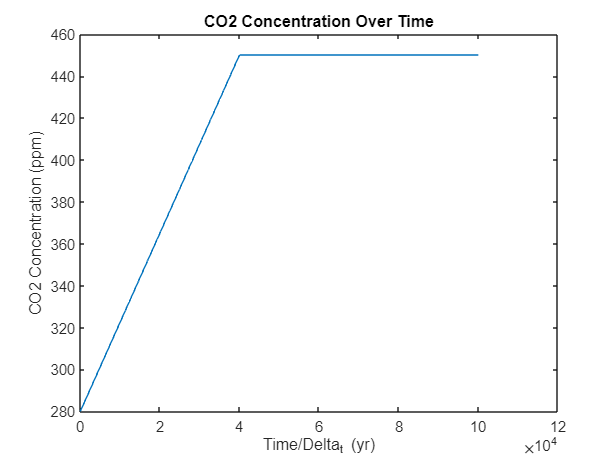

% Generate CO2 Profile
delta_t = 0.005; %yr
t_final = 500;
t = 0:delta_t:t_final; %yr
n_t = length(t);

C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200/delta_t); %ppm
for k = 1:(n_t-(200/delta_t))
    C_1900_2100(end+1) = C_post2100;
end

plot(C_1900_2100)
title('CO2 Concentration Over Time');
xlabel('Time/Delta_t (yr)'); ylabel('CO2 Concentration (ppm)')

The above figure demostrates the standard atmospheric CO2 profile with time for most of the following simulations. The x axis is in time in years per change in time because that is how it needs to be formatted to embed itself into the method. The profile is exacly as described in the text that provided the scenario with a period of increasing CO2 for 200 years followed by a stable level for the remaining time. These ppm values are a simulation of CO2 rise from 1900 to 2100.

## Run an Example Model with Oscilating CO2 Concentration

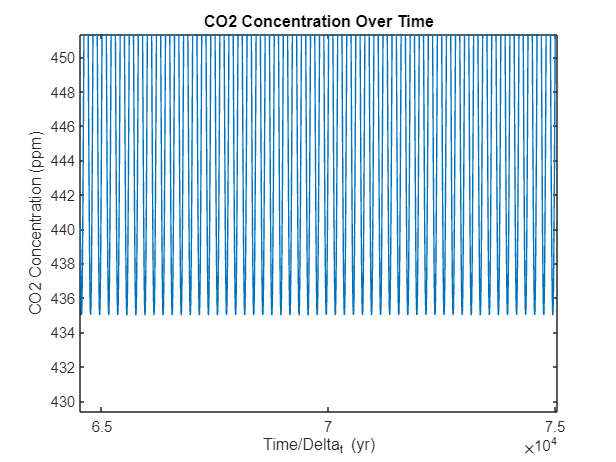

% Define Parameters
CO2_solub = 2*10^(-6); %mol/(cm^3*ppm)
CO2_solub = CO2_solub/(1*10^(-6)); %mol/(m^3*ppm)
D = 1*10^(-7); %cm^2/s
D = D*3153.6; %m^2/yr
w = 0.1; %m/yr
t_final = 500; %yr

% Define Grid
delta_t = 0.005; %yr
t = 0:delta_t:t_final; %yr
n_t = length(t);

x_final = t_final*w; %m
delta_x = 1; %m
x = 0:delta_x:x_final+delta_x; %m
n_x = length(x);

C_num = w*delta_t/delta_x; %Courant Number
D_P = D*delta_t/(delta_x^2);

% Preallocate Atmospheric CO2
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200/delta_t); %ppm
for k = 1:(n_t-(200/delta_t))
    C_1900_2100(end+1) = C_post2100;
end

for k = 1:n_t
    C_1900_2100(k) = C_1900_2100(k) + 15*sin(2*pi*k*delta_t); %Average CO2 Oscilation ~15 ppm per year.
end

plot(C_1900_2100)
title('CO2 Concentration Over Time');
xlabel('Time/Delta_t (yr)'); ylabel('CO2 Concentration (ppm)')

The above figure is similar to the first as it models the same values and general trend. The key difference is the addition of a deviation of CO2 concentration due to seasonal effects. The deviation appears to be a solid block in the figure because the time scale ranges from zero to five hundred years, so individual oscillations require enhancing the zoom of the figure to observe. It is important to note that the number of time stages is large enough to model each oscillation and not cut off the definition of the change. In the real world, CO2 concentration increases during the winter months due to the decrease in photosynthetic activity on Earth and decreases in summer months for the opposite reason. The oscillations in this figure work to model this temporal trend.

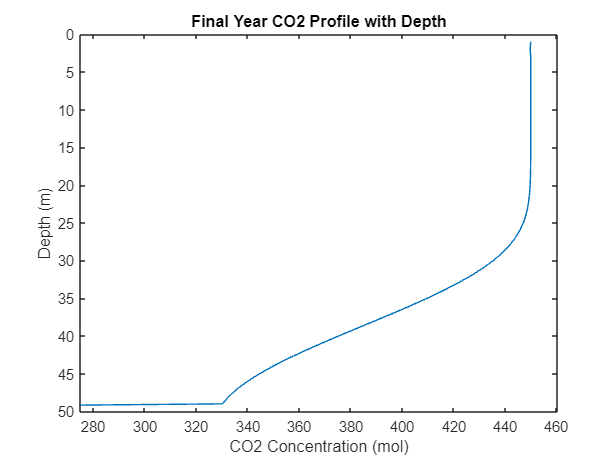

C = zeros(n_x+1,n_t);
C(1,:) = C_1900_2100;

% Prevent Snow from Diffusing into Grid Spaces too Soon
snow = zeros(n_x, n_t);
for k = 1:n_t
    for i = 1:n_x
        if (i - k*delta_t*w) == 0
            snow(i,k) = 2;
        end
        if (i - k*delta_t*w) < 0
            snow(i,k) = 1;
        end
    end
end

% Solve
for k = 1:(n_t-1)
    for i = 2:(n_x-1)
        if snow(i,k) == 1 %Normal Advection Diffusion
            C(i,k+1) = C(i,k) - C_num*(C(i,k) - C(i-1,k)) + D_P*(C(i+1,k) - 2*C(i,k) + C(i-1,k));
        end
        if snow(i,k) == 2 %No flux boundary
            C(i,k+1) = C(i-1,k);
        end
        if snow(i,k) == 0 %Out of Snow Bounds
            C(i,k+1) = 0;
        end
    end
end


plot(C(:,end-1));
set(gca, 'XDir','reverse');
view([90 -90]);
xlim([0 x_final]);
ylim([275 max(C(:,end))+10]);
xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth')

The above figure shows the final year CO2 profile with depth. The horizontal line at the bottom of the graph is where there is no snow. The curve above this position is the entrained CO2 concentration from the initial advection at the time the ice formed.

## **Animation 2**

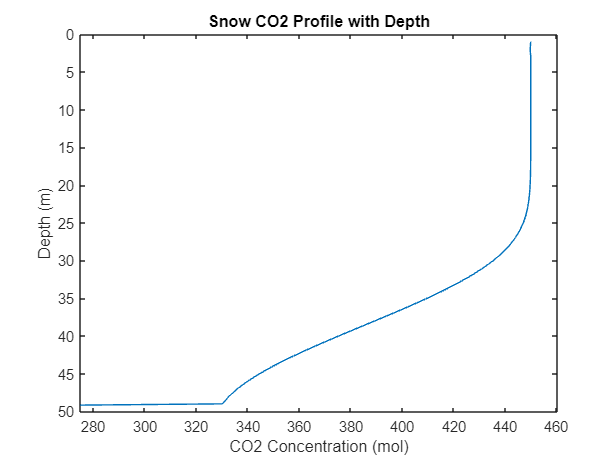

figure;
for i = 1:(n_t/100)
    plot(C(:,i*100))
    set(gca, 'XDir','reverse');
    view([90 -90]);
    xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
    title('Snow CO2 Profile with Depth')
    xlim([0 x_final]);
    ylim([275 max(C(:,end))+10]);
    drawnow
end

The above animation shows the change in CO2 concentration with time and depth. There is a present oscillation at the top of the animation where the atmospheric seasonal changes occur. The short depth of this effect is due to the comparatively high time scales of the diffusion constant to the seasonal change.

### **Time 1**

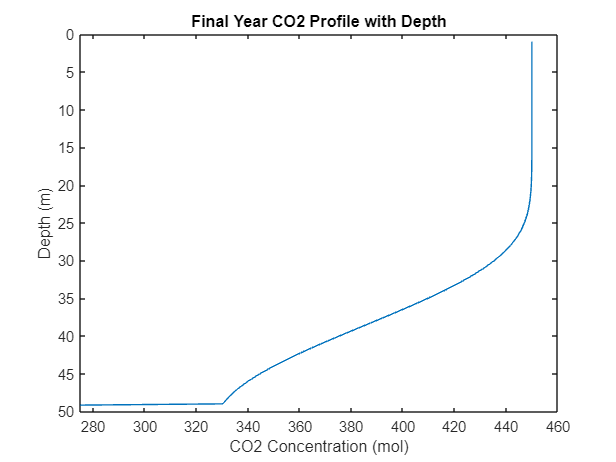

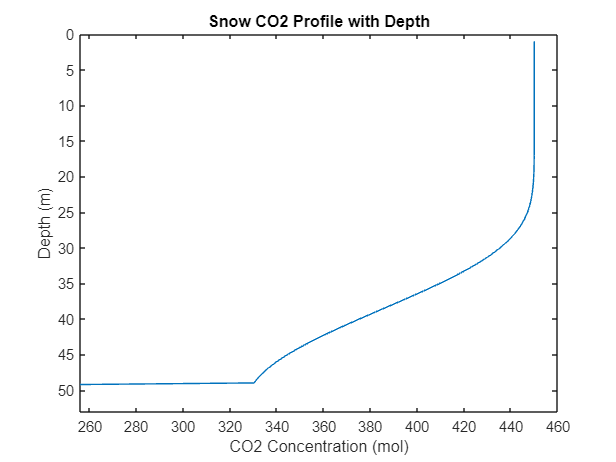

Peclet = 317.0979

adv_diff1(0.1,500)

These figures demonstrate the first set of conditions being simulated: a time length of 500 years and a snowfall rate of 0.1 meters per year. The animation and final year figure are relatively similar to the simulation with seasonal effects while the slope of snow at the bottom of the figure matches identically. This Peclet number demonstrates that advection strongly outpaces diffusion in this scenario. The application of the Peclet number in the real world describes the usefullness of ice cores in describing the concentration of atmospheric gases in past climates. If diffusion were to outpace advection, then the CO2 profile would look more like a vertical line where depth does not change the present concentration of CO2.

### **Time 2**

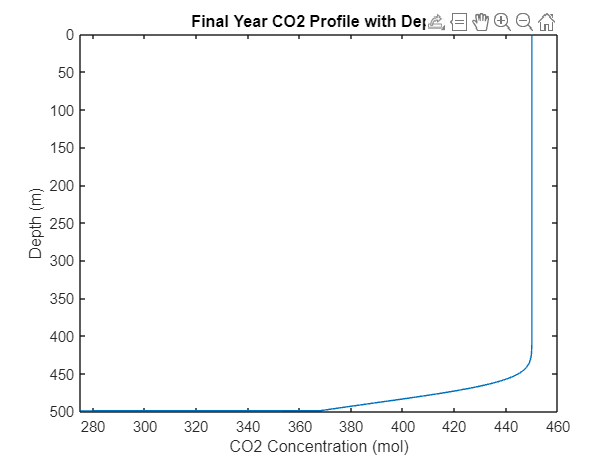

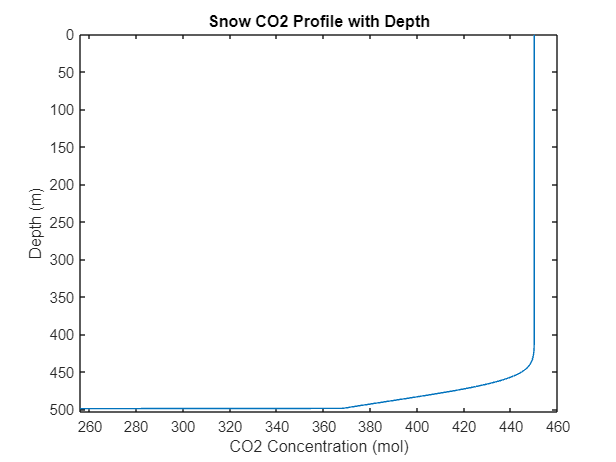

Peclet = 317.0979

adv_diff1(0.1,5000)

This simulation alters the final time from 500 years to 5,000 years into the future. Although there is no time axis on the graph, depth is dependent on time in this problem. Comparatively, the final time for this simulation is ten times that of the previous one, and the final depth is also ten times deeper than the previous simulation. The change in time scale here makes the transition layer at the bottom of the ice core seem larger, but this is solely due to the previously mentioned increase in depth scale. For practical applications, if the Peclet number is large enough, then increasing the time from the occurence of the climate event does not significantly alter the profile of the ice core at that time. However, this model assumes constant snowfall, but in reality this would be a non-linear relationship between time and snow deposition. 

### **w 1**

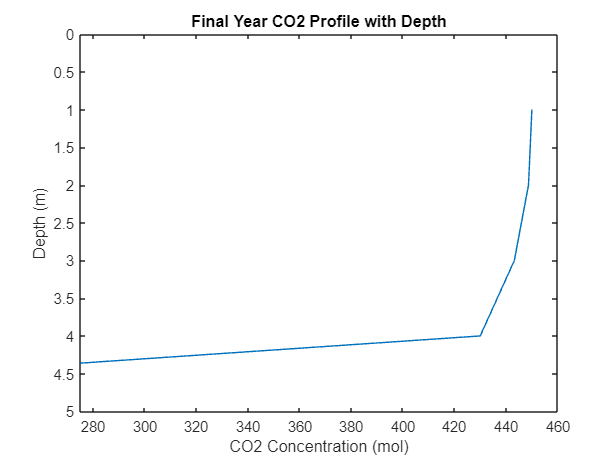

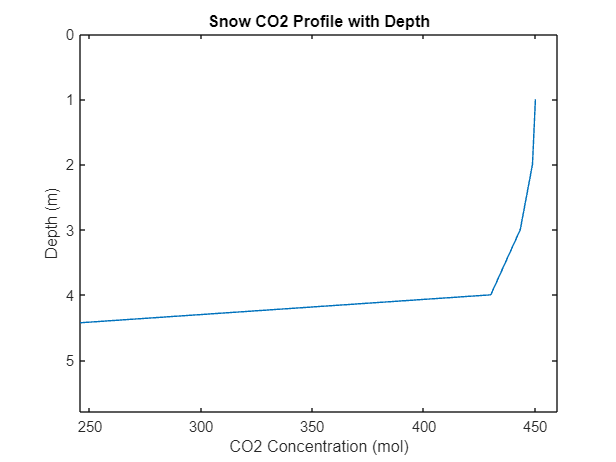

Peclet = 31.7098

adv_diff1(0.01,500)

This simulation shows a model run with the same final time of 500 years, but with a significantly lower snow deposition rate of 0.01 meters per year. Because the depth scale and increments of time and depth are changed by the snow deposition rate above, the change in CO2 concentration with depth appears jagged. Decreasing the snow deposition inadvertently increases the effect of diffusion because there is far less depth scale to diffuse through. This explains why the low level slope of CO2 is far sharper here than in the first couple runs. The Peclet number here is one order of magnitude lower than in the previous simulation. This confirms an increase in the effects of diffusion corresponding with a decrease in snow depositon.

### **w 2**

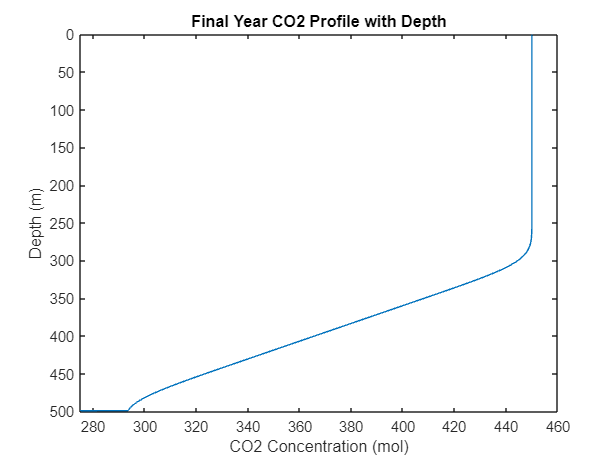

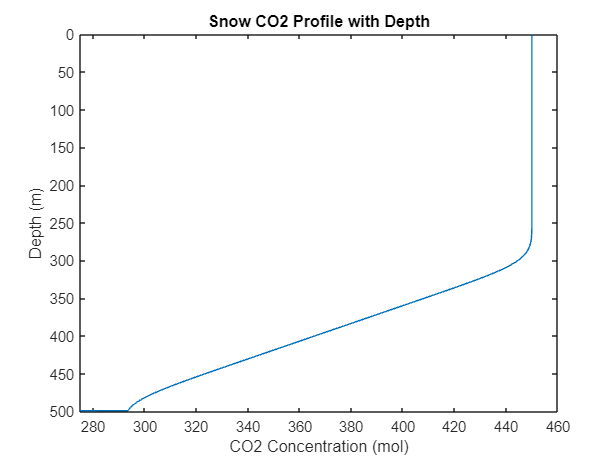

Peclet = 3.1710e+03

adv_diff1(1,500)

This simulation shows the modeled run with the same final time but increased snow deposition to one meter every year. As seen in the above figure and animation, the slope of the deeper ice is far smaller than that of any previous simulation. This smaller slope better preserves the change in atmopsheric CO2 that would be seen in a model run without diffusion. The Peclet number confirms this theory as it is an order of magnitude larger than the control run (the simulation using the conditions set by the text). This means that advection strongly outweighs diffusion for this simulation.

## **Function**

function adv_diff1(w,t_final)
% Define Parameters
CO2_solub = 2*10^(-6); %mol/(cm^3*ppm)
CO2_solub = CO2_solub/(1*10^(-6)); %mol/(m^3*ppm)
D = 1*10^(-7); %cm^2/s
D = D*3153.6; %m^2/yr

% Define Grid
delta_t = 0.005; %yr
t = 0:delta_t:t_final; %yr
n_t = length(t);

x_final = t_final*w; %m
delta_x = 1; %m
x = 0:delta_x:x_final+delta_x; %m
n_x = length(x);

C_num = w*delta_t/delta_x; %Courant Number
D_P = D*delta_t/(delta_x^2);

% Generate CO2 Profile
C_pre1900 = 280; %ppm
C_post2100 = 450; %ppm
C_1900_2100 = linspace(C_pre1900, C_post2100, 200/delta_t); %ppm
for k = 1:(n_t-(200/delta_t))
    C_1900_2100(end+1) = C_post2100;
end
C = zeros(n_x+1,n_t);
C(1,:) = C_1900_2100;

% Prevent Snow from Diffusing into Grid Spaces too Soon
snow = zeros(n_x, n_t);
for k = 1:n_t
    for i = 1:n_x
        if (i - k*delta_t*w) == 0
            snow(i,k) = 2;
        end
        if (i - k*delta_t*w) < 0
            snow(i,k) = 1;
        end
    end
end

% Solve
for k = 1:(n_t-1)
    for i = 2:(n_x-1)
        if snow(i,k) == 1 %Normal Advection Diffusion
            C(i,k+1) = C(i,k) - C_num*(C(i,k) - C(i-1,k)) + D_P*(C(i+1,k) - 2*C(i,k) + C(i-1,k));
        end
        if snow(i,k) == 2 %No flux boundary
            C(i,k+1) = C(i-1,k);
        end
        if snow(i,k) == 0 %Out of Snow Bounds
            C(i,k+1) = 0;
        end
    end
end

% Final Year Plot
plot(C(:,end-1));
set(gca, 'XDir','reverse');
view([90 -90]);
xlim([0 x_final]);
ylim([275 max(C(:,end))+10]);
xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
title('Final Year CO2 Profile with Depth')

% Animation
figure;
for i = 1:(n_t/100)
    plot(C(:,i*100))
    set(gca, 'XDir','reverse');
    view([90 -90]);
    xlabel('Depth (m)'); ylabel('CO2 Concentration (mol)');
    title('Snow CO2 Profile with Depth')
    xlim([0 x_final]);
    ylim([275 max(C(:,end))+10]);
    drawnow
end

Peclet = w*delta_x/D
end

## **Video Walkthrough**

[https://youtu.be/GPUDqMNpRJU?si=62ys8hLxjOXnLbwq](https://youtu.be/GPUDqMNpRJU?si=62ys8hLxjOXnLbwq)

## **References**

Bender, Michael, et al. “Gases in ice cores.” *Proceedings of the National Academy of Sciences*, vol. 94, no. 16, 1997, pp. 8343–8349, https://doi.org/10.1073/pnas.94.16.8343. 

Legrand, Michel, and Paul Mayewski. “Glaciochemistry of polar ice cores: A Review.” *Reviews of Geophysics*, vol. 35, no. 3, 1997, pp. 219–243, https://doi.org/10.1029/96rg03527. 

*Oxford English Dictionary*, www.oed.com/. Accessed 2 Dec. 2023. 

Slingerland, Rudy, and Lee R. Kump. “Advection and Diffusion (Transport) Problems.” *Mathematical Modeling of Earth’s Dynamical Systems: A Primer*, Princeton University Press, Princeton, 2006, pp. 124–125. 